We generate a piecewise linear interpolant of $f(x)=e^{\sin 7x}$. 

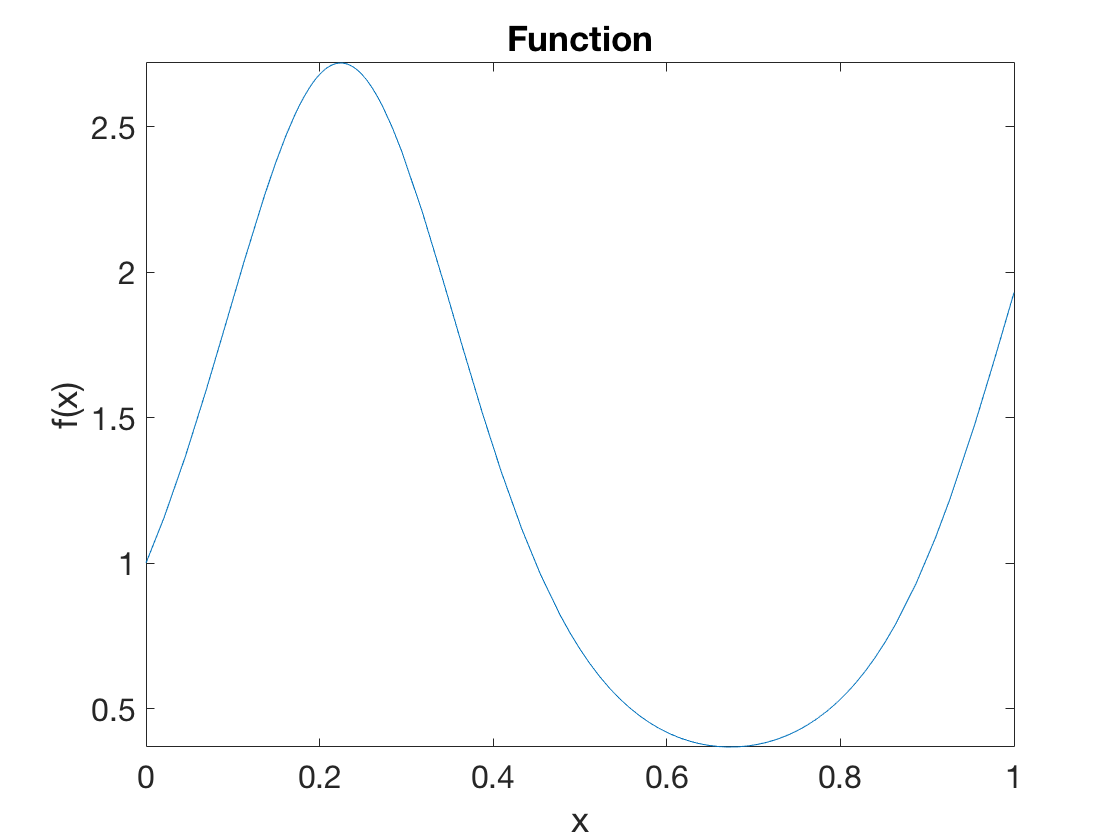

f = @(x) exp(sin(7*x));
fplot(f,[0 1])
xlabel('x'), ylabel('f(x)')    % ignore this line
title('Function')    % ignore this line

First we sample the function to create the data.

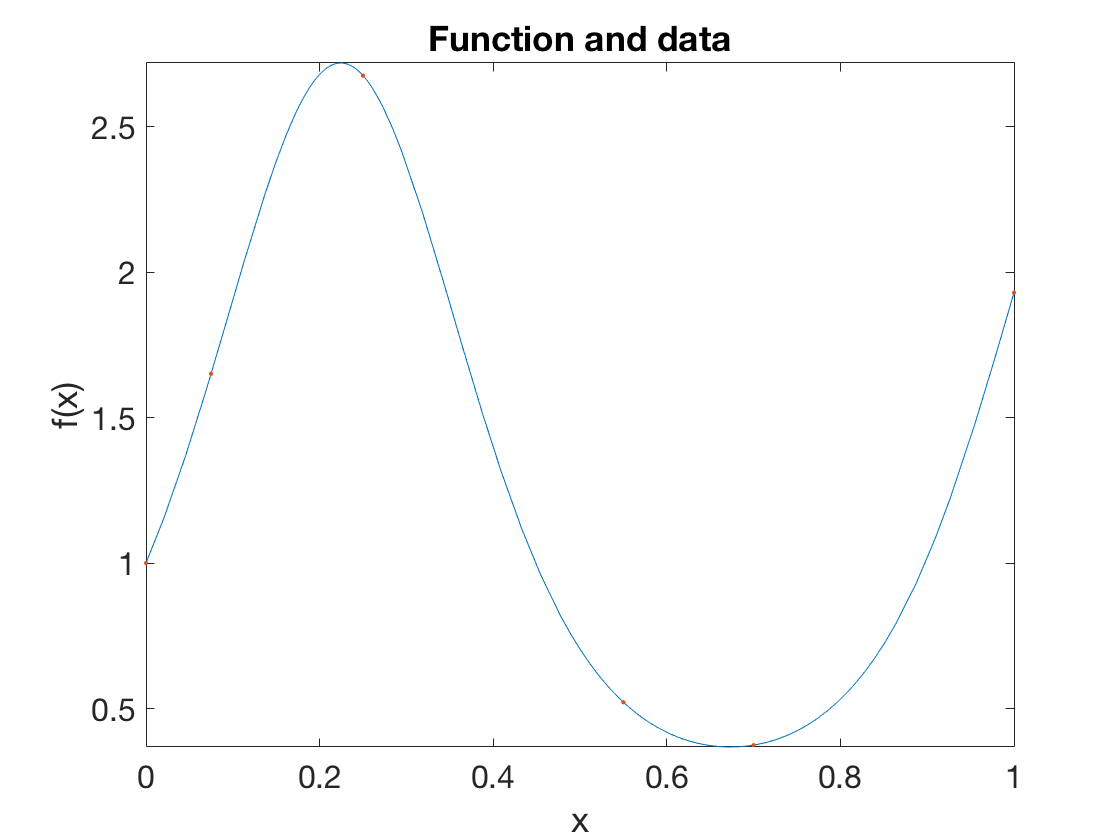

t = [0 0.075 0.25 0.55 0.7 1];    % nodes
y = f(t);
hold on, plot(t,y,'.')
title('Function and data')    % ignore this line

Now we create a callable function that will evaluate the piecewise linear interpolant at any $x$.

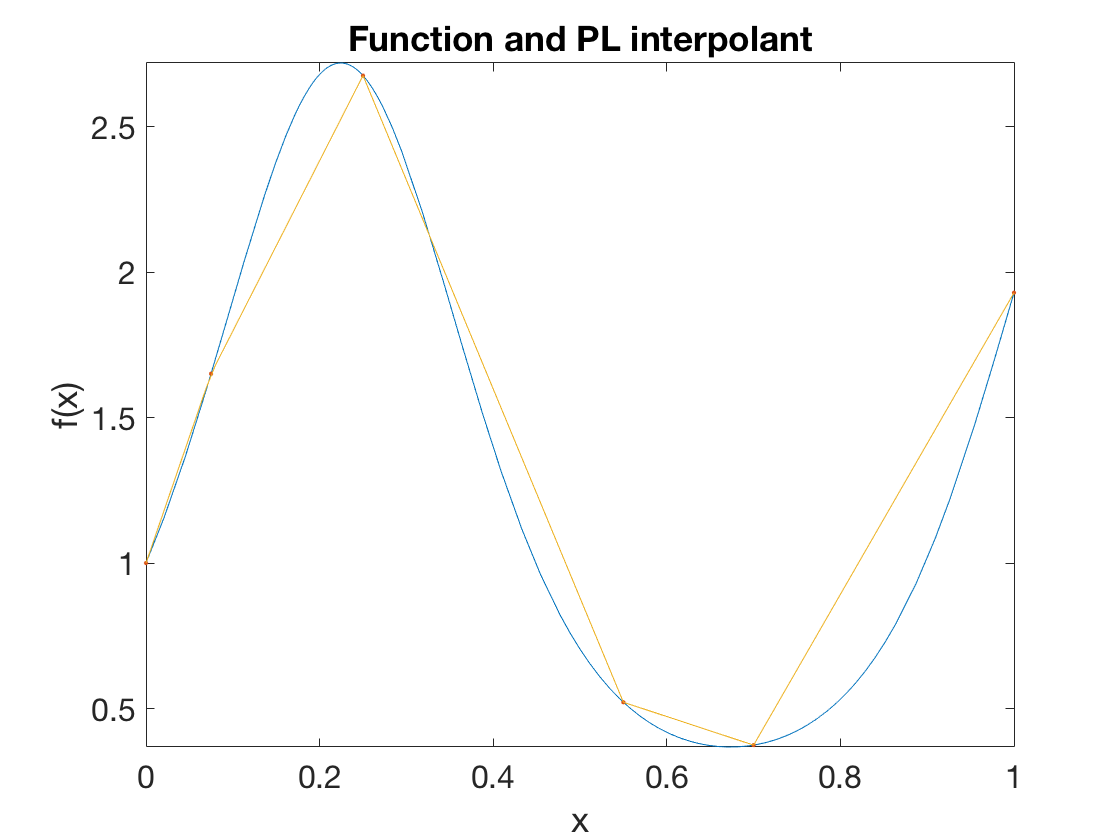

p = plinterp(t,y);
fplot(p,[0 1])
title('Function and PL interpolant')    % ignore this line